Patient 1 Post Clinic Summary Right 

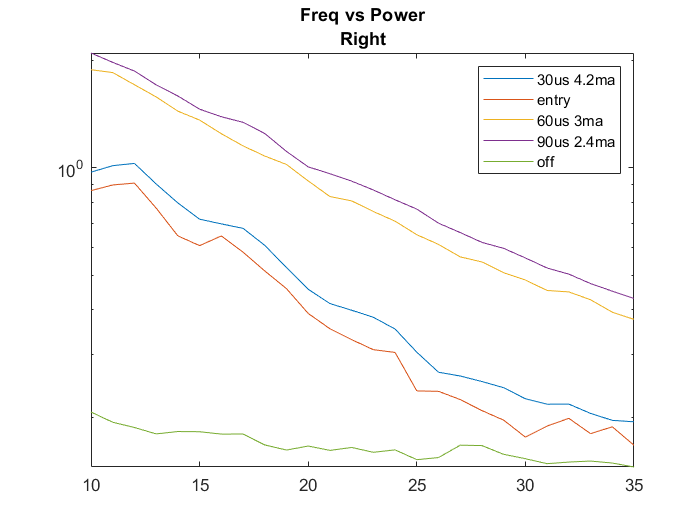

clear all;
figure; 
%get the json 
cd('C:\Users\sydne\Documents\github\perceive\patientData')
jsonFiles = 'Report_Json_Session_Report_patient1_right_final.json'; 
js = jsondecode(fileread(jsonFiles));
%set back to the correct directory 
cd('C:\Users\sydne\Documents\github\perceive\postAnalysis') 
%% create a struct of the relevant data from brainsense 
leng = numel(js.BrainSenseLfp);
data = struct;
for i=1:leng
    x = num2str(i);
    field = append("treatment", x);
    data.(field).channel = js.BrainSenseLfp(i).Channel;
    data.(field).time = datetime(replace({js.BrainSenseLfp(i).FirstPacketDateTime}, {'T', 'Z'},  {' ', ''}));
    data.(field).pw = js.BrainSenseLfp(i).TherapySnapshot.Right.PulseWidthInMicroSecond;
    data.(field).ma = js.BrainSenseLfp(i).TherapySnapshot.Right.LowerLimitInMilliAmps;
    data.(field).timeDomain = js.BrainSenseTimeDomain(i).TimeDomainData;
end
%% do pwelch on the LFP recording
%uncomment the subplot lines to just create a 5x1 subplot 
fs=250;
nfft=250;
window=250;
overlap=150;
%subplot(leng, 1, 1)
for i=1:leng
    %make i usable for indexing into the struct 
    x = num2str(i);
    field = append("treatment", x);
    %calculate values
    t = data.(field).timeDomain;
    [pxx,f] = pwelch(t,window,overlap,nfft,fs);
    data.(field).LFPpower = pxx;
    data.(field).freq = f;
    fbeta = f > 12 & f < 33; 
    data.(field).avg = mean(pxx(fbeta));
    
    %subplot(leng, 1, i)
    semilogy(f,sqrt(pxx))
    xlim([10 35])
    hold on
end
title(["Freq vs Power", "Right"])

%get legend info 
%some parts must be hard coded bc 
for i = 1:leng 
    x = num2str(i);
    field = append("treatment", x);
    pw = num2str(data.(field).pw); 
    ma = num2str(data.(field).ma);
    legendVal{i} = ((append(pw, "us ", ma, "ma")));
end 


%MANUALLY SET THESE BASED UPON THE PATIENT SUMMARY
legendVal{5} = "off";
legendVal{2} = "entry";


legend(legendVal{1}, legendVal{2}, legendVal{3}, legendVal{4}, legendVal{5});



for i = 1:leng 
    x = num2str(i);
    field = append("treatment", x);
    means(i) = data.(field).avg;
end 

Tmean = array2table(means', 'VariableNames', {'Average Power in Beta Region (mV)'});
Tname = cell2table(legendVal', 'VariableNames', {'Treatment'}); 
tbl = [Tname Tmean];
sortrows(tbl, {'Average Power in Beta Region (mV)'}, 'descend')

ans = 5×2 table
     Treatment      Average Power in Beta Region (mV)
    ____________    _________________________________

    "90us 2.4ma"                  1.0703             
    "60us 3ma"                   0.85518             
    "30us 4.2ma"                 0.24343             
    "entry"                      0.17672             
    "off"                       0.027309             


Patient 1 Post Clinic Summary Left 

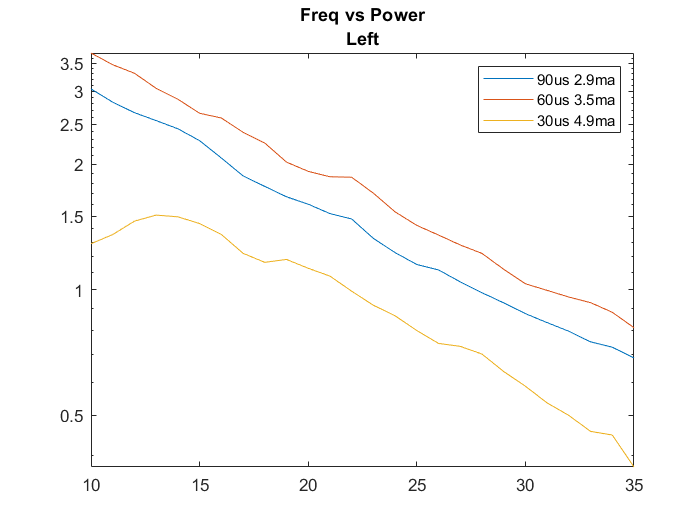

clear all;
figure; 
%get the json 
cd('C:\Users\sydne\Documents\github\perceive\patientData')
jsonFiles = 'Report_Json_Session_Report_patient1_left_final.json'; 
js = jsondecode(fileread(jsonFiles));
%set back to the correct directory 
cd('C:\Users\sydne\Documents\github\perceive\postAnalysis') 
%% create a struct of the relevant data from brainsense 
leng = numel(js.BrainSenseLfp);
data = struct;
for i=1:leng
    x = num2str(i);
    field = append("treatment", x);
    data.(field).channel = js.BrainSenseLfp(i).Channel;
    data.(field).time = datetime(replace({js.BrainSenseLfp(i).FirstPacketDateTime}, {'T', 'Z'},  {' ', ''}));
    data.(field).pw = js.BrainSenseLfp(i).TherapySnapshot.Left.PulseWidthInMicroSecond;
    data.(field).ma = js.BrainSenseLfp(i).TherapySnapshot.Left.LowerLimitInMilliAmps;
    data.(field).timeDomain = js.BrainSenseTimeDomain(i).TimeDomainData;
end
%% do pwelch on the LFP recording
%uncomment the subplot lines to just create a 5x1 subplot 
fs=250;
nfft=250;
window=250;
overlap=150;
%subplot(leng, 1, 1)
for i=1:leng
    %make i usable for indexing into the struct 
    x = num2str(i);
    field = append("treatment", x);
    %calculate values
    t = data.(field).timeDomain;
    [pxx,f] = pwelch(t,window,overlap,nfft,fs);
    data.(field).LFPpower = pxx;
    data.(field).freq = f;
    fbeta = f > 12 & f < 33; 
    data.(field).avg = mean(pxx(fbeta));
    
    %subplot(leng, 1, i)
    semilogy(f,sqrt(pxx))
    xlim([10 35])
    hold on
end
title(["Freq vs Power", "Left"])

%get legend info 
%some parts must be hard coded bc 
for i = 1:leng 
    x = num2str(i);
    field = append("treatment", x);
    pw = num2str(data.(field).pw); 
    ma = num2str(data.(field).ma);
    legendVal{i} = ((append(pw, "us ", ma, "ma")));
end 


%MANUALLY SET THESE BASED UPON THE PATIENT SUMMARY
% legendVal{2} = "off";
% legendVal{3} = "entry";


legend(legendVal{1}, legendVal{2}, legendVal{3});



for i = 1:leng 
    x = num2str(i);
    field = append("treatment", x);
    means(i) = data.(field).avg;
end 

Tmean = array2table(means', 'VariableNames', {'Average Power in Beta Region (mV)'});
Tname = cell2table(legendVal', 'VariableNames', {'Treatment'}); 
tbl = [Tname Tmean];
sortrows(tbl, {'Average Power in Beta Region (mV)'}, 'descend')

ans = 3×2 table
     Treatment      Average Power in Beta Region (mV)
    ____________    _________________________________

    "60us 3.5ma"                 3.6669              
    "90us 2.9ma"                 2.4678              
    "30us 4.9ma"                 1.0609              
